% Experiment-5: Bounding Box Cropped Images with 5-Fold Cross Validation CNN:
% CUB_200_2011
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

rng(42, 'twister'); %% For reproducibility

%% STEP 1: Check and Reset GPU
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device); % Reset any old data
else
    error('No GPU device found. Please ensure GPU is available.');
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Setup Paths


folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";
imgFolder = folder + "images/";
imgTxtFolder = folder + "images.txt"; % Needed for bounding box mapping
targetSize = [128, 128];

## Load All Images into a Single Datastore

allImageDS = imageDatastore(imgFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

## Split into 5 folds (each 20%)

[fold1DS, fold2DS, fold3DS, fold4DS, fold5DS] = splitEachLabel(allImageDS, 0.2, 0.2, 0.2, 0.2);

## Create a simple CNN

%% Create CNN Layers
layers = [
    imageInputLayer([128 128 3], 'Normalization', 'zerocenter') 

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 256, 'Padding', 'same')  % NEW BLOCK 
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 512, 'Padding', 'same')  % NEW BLOCK 
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(200, 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    softmaxLayer
    classificationLayer];


## Cross Validation Loop

Running Fold 1


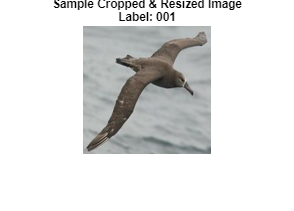

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:37 |        0.00% |        0.81% |       6.2820 |      18.1658 |          0.0005 |
|       1 |           2 |       00:00:38 |        1.56% |              |      17.9866 |              |          0.0005 |
|       1 |           3 |       00:00:38 |        0.00% |              |      22.4283 |              |          0.0005 |
|       1 |           4 |       00:00:39 |        0.00% |              |      24.1771 |              |          0.

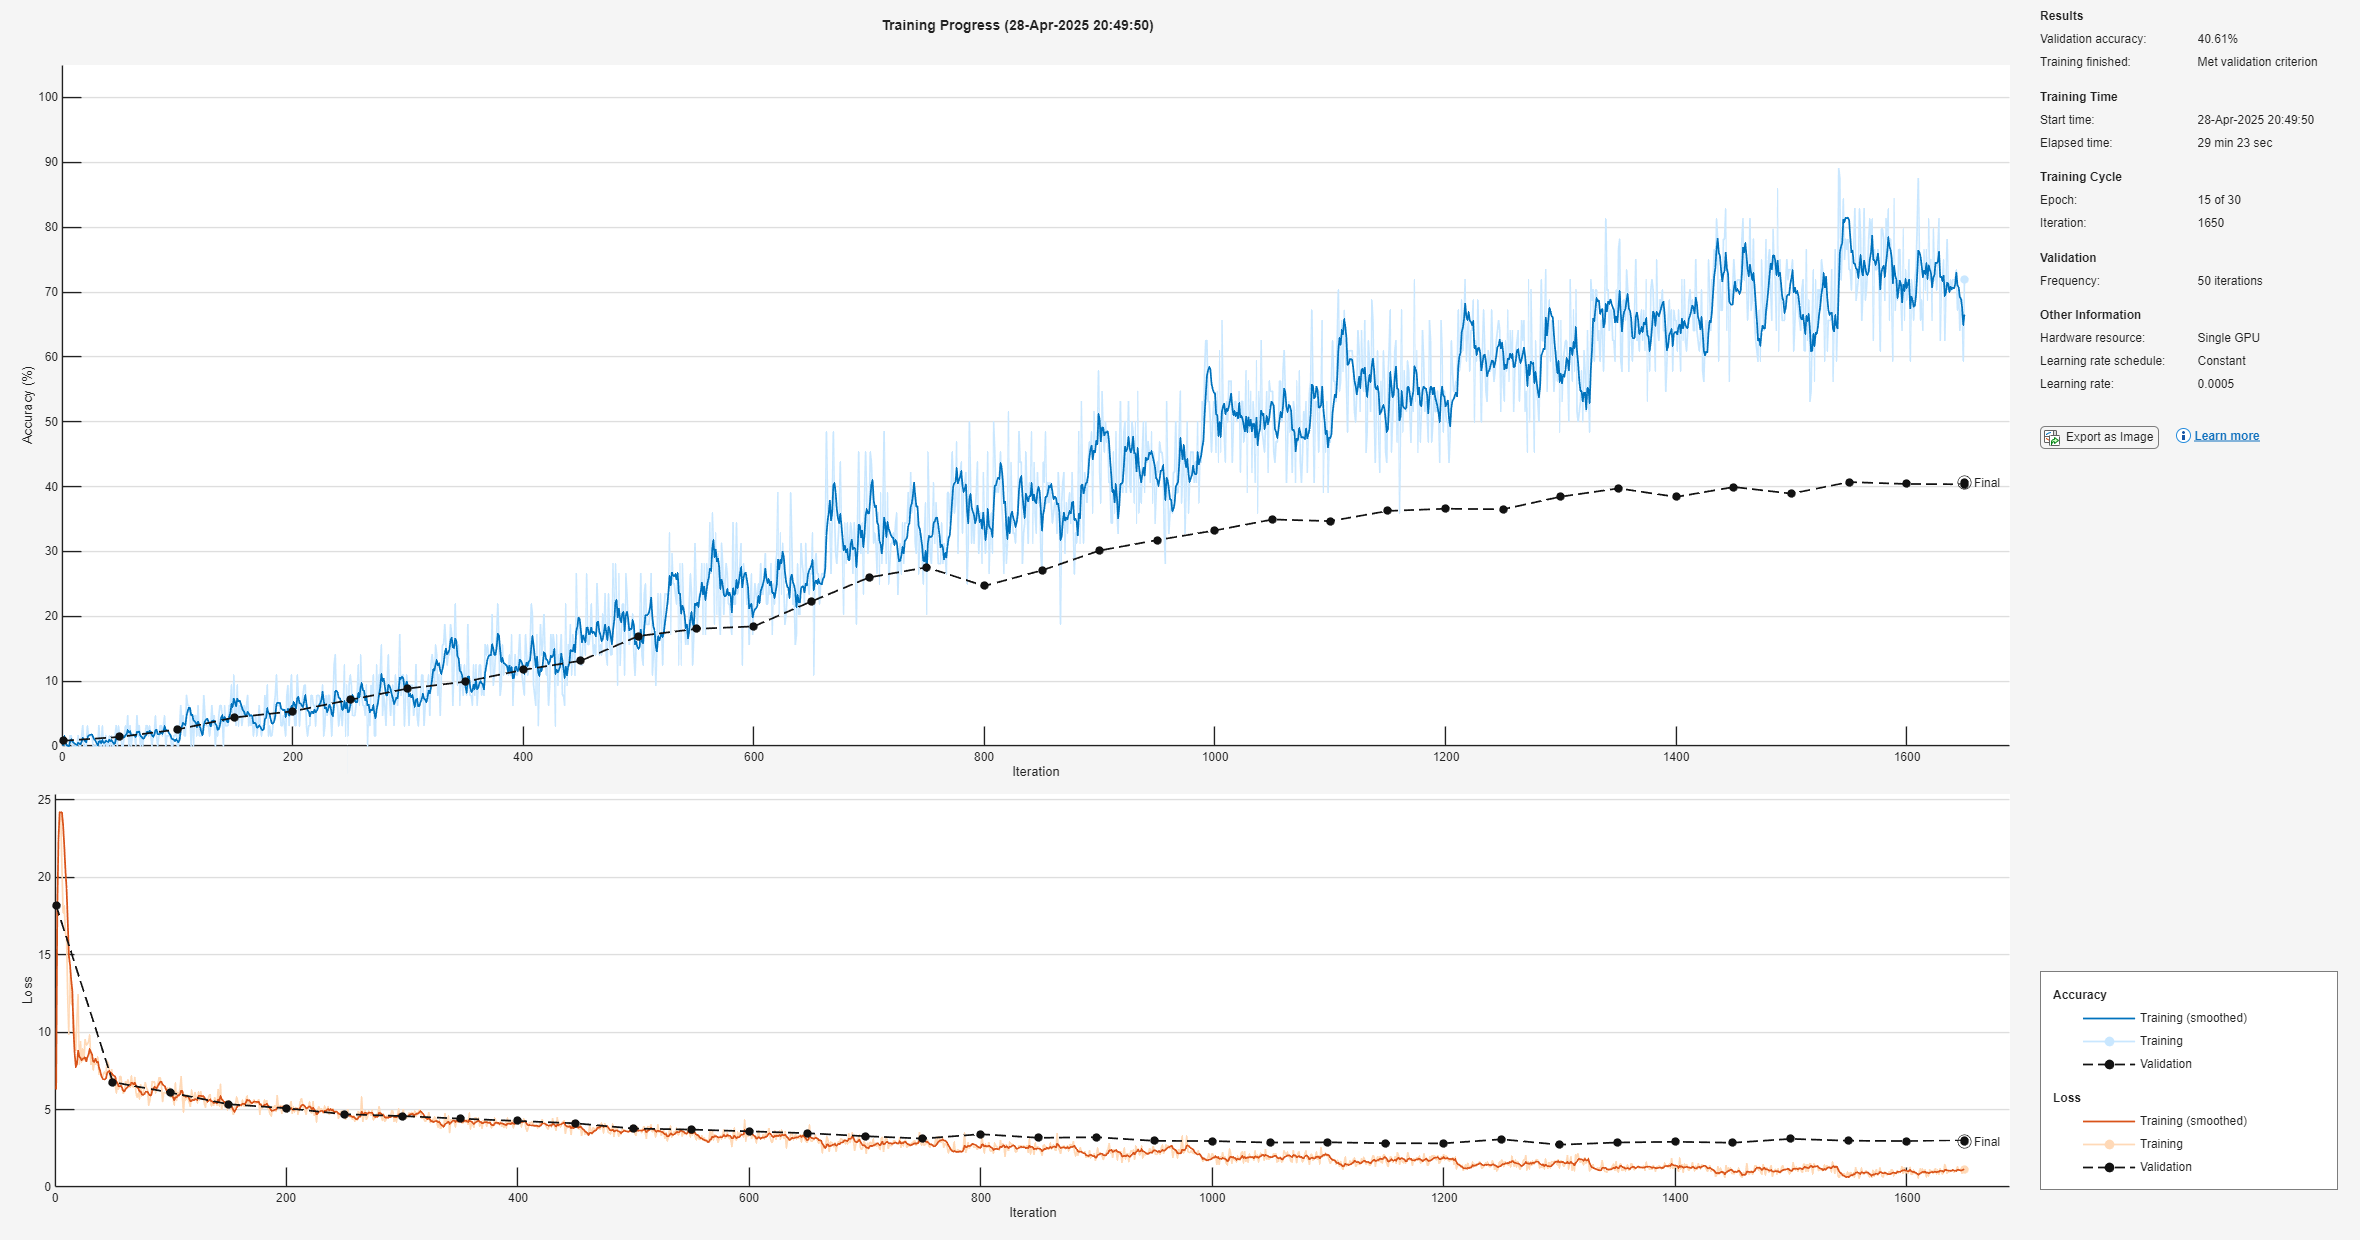

Accuracy for Fold 1: 41.50%


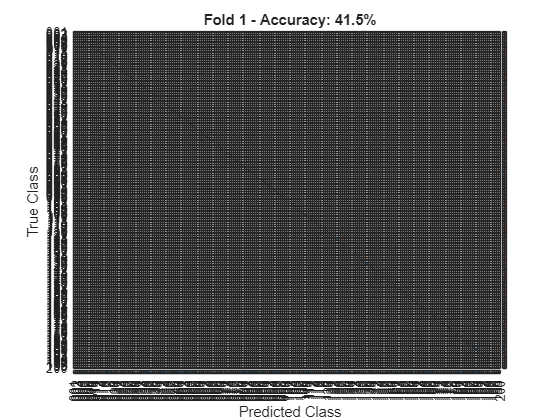

Running Fold 2


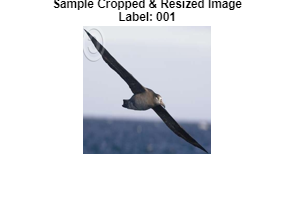

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:28 |        0.00% |        0.97% |       7.0286 |      17.8875 |          0.0005 |
|       1 |           2 |       00:00:29 |        0.00% |              |      16.4268 |              |          0.0005 |
|       1 |           3 |       00:00:30 |        1.56% |              |      24.5929 |              |          0.0005 |
|       1 |           4 |       00:00:30 |        0.00% |              |      25.8845 |              |          0.

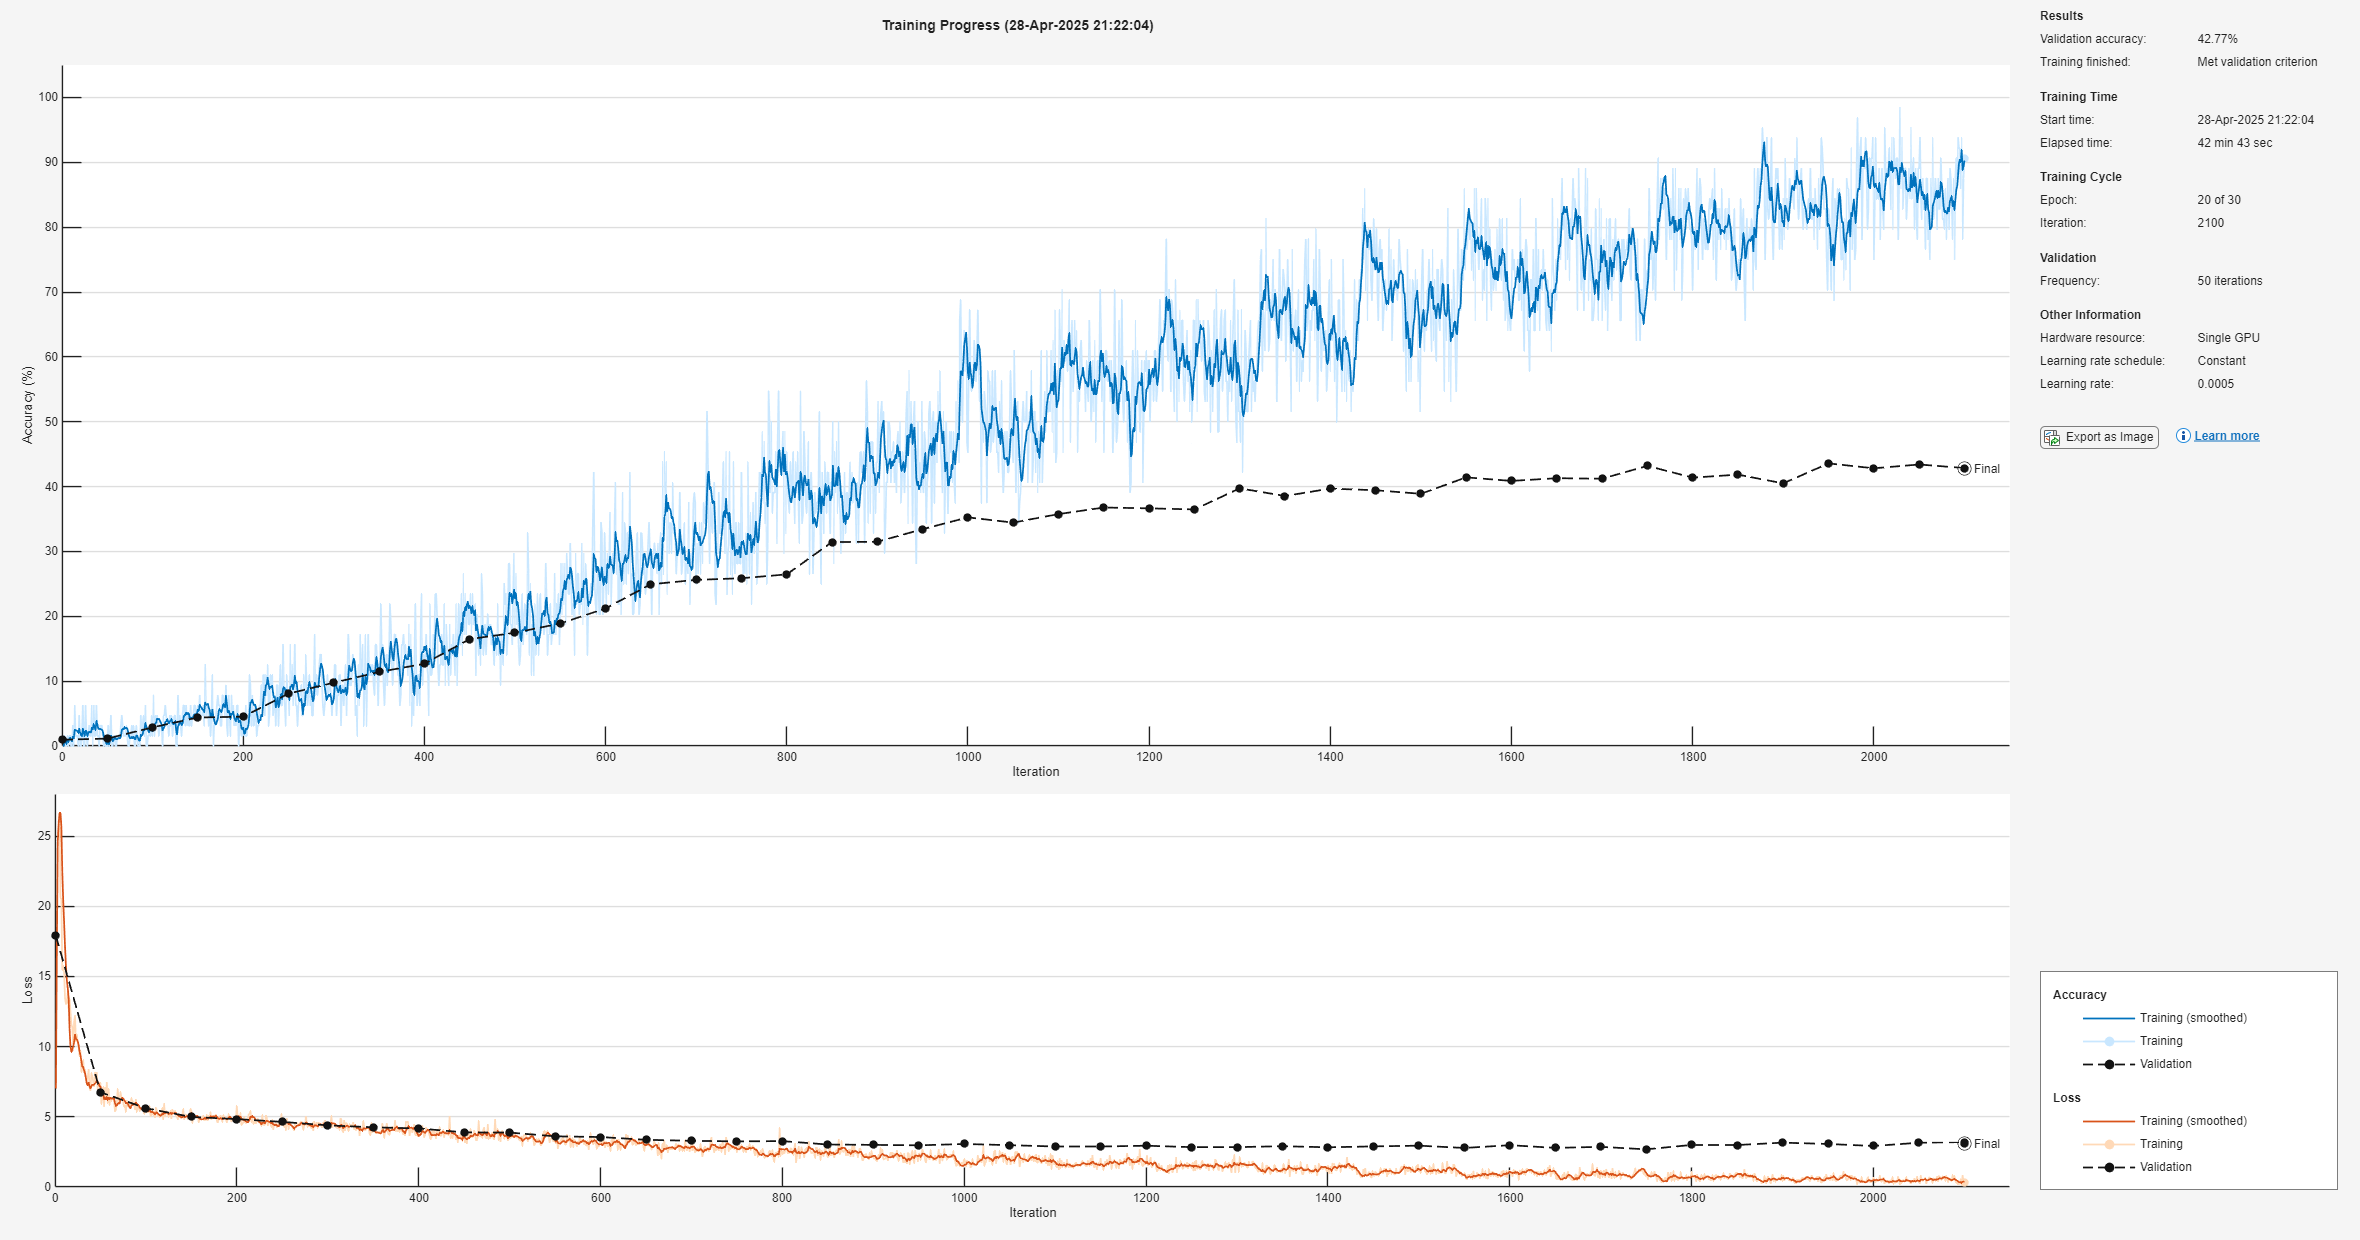

Accuracy for Fold 2: 43.11%


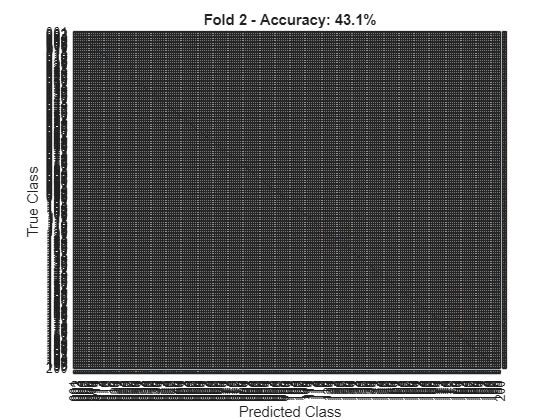

Running Fold 3


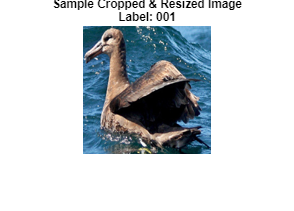

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |        0.00% |        0.85% |       6.2717 |      18.1954 |          0.0005 |
|       1 |           2 |       00:00:22 |        1.56% |              |      19.6552 |              |          0.0005 |
|       1 |           3 |       00:00:30 |        4.69% |              |      23.0237 |              |          0.0005 |
|       1 |           4 |       00:00:31 |        1.56% |              |      24.0264 |              |          0.

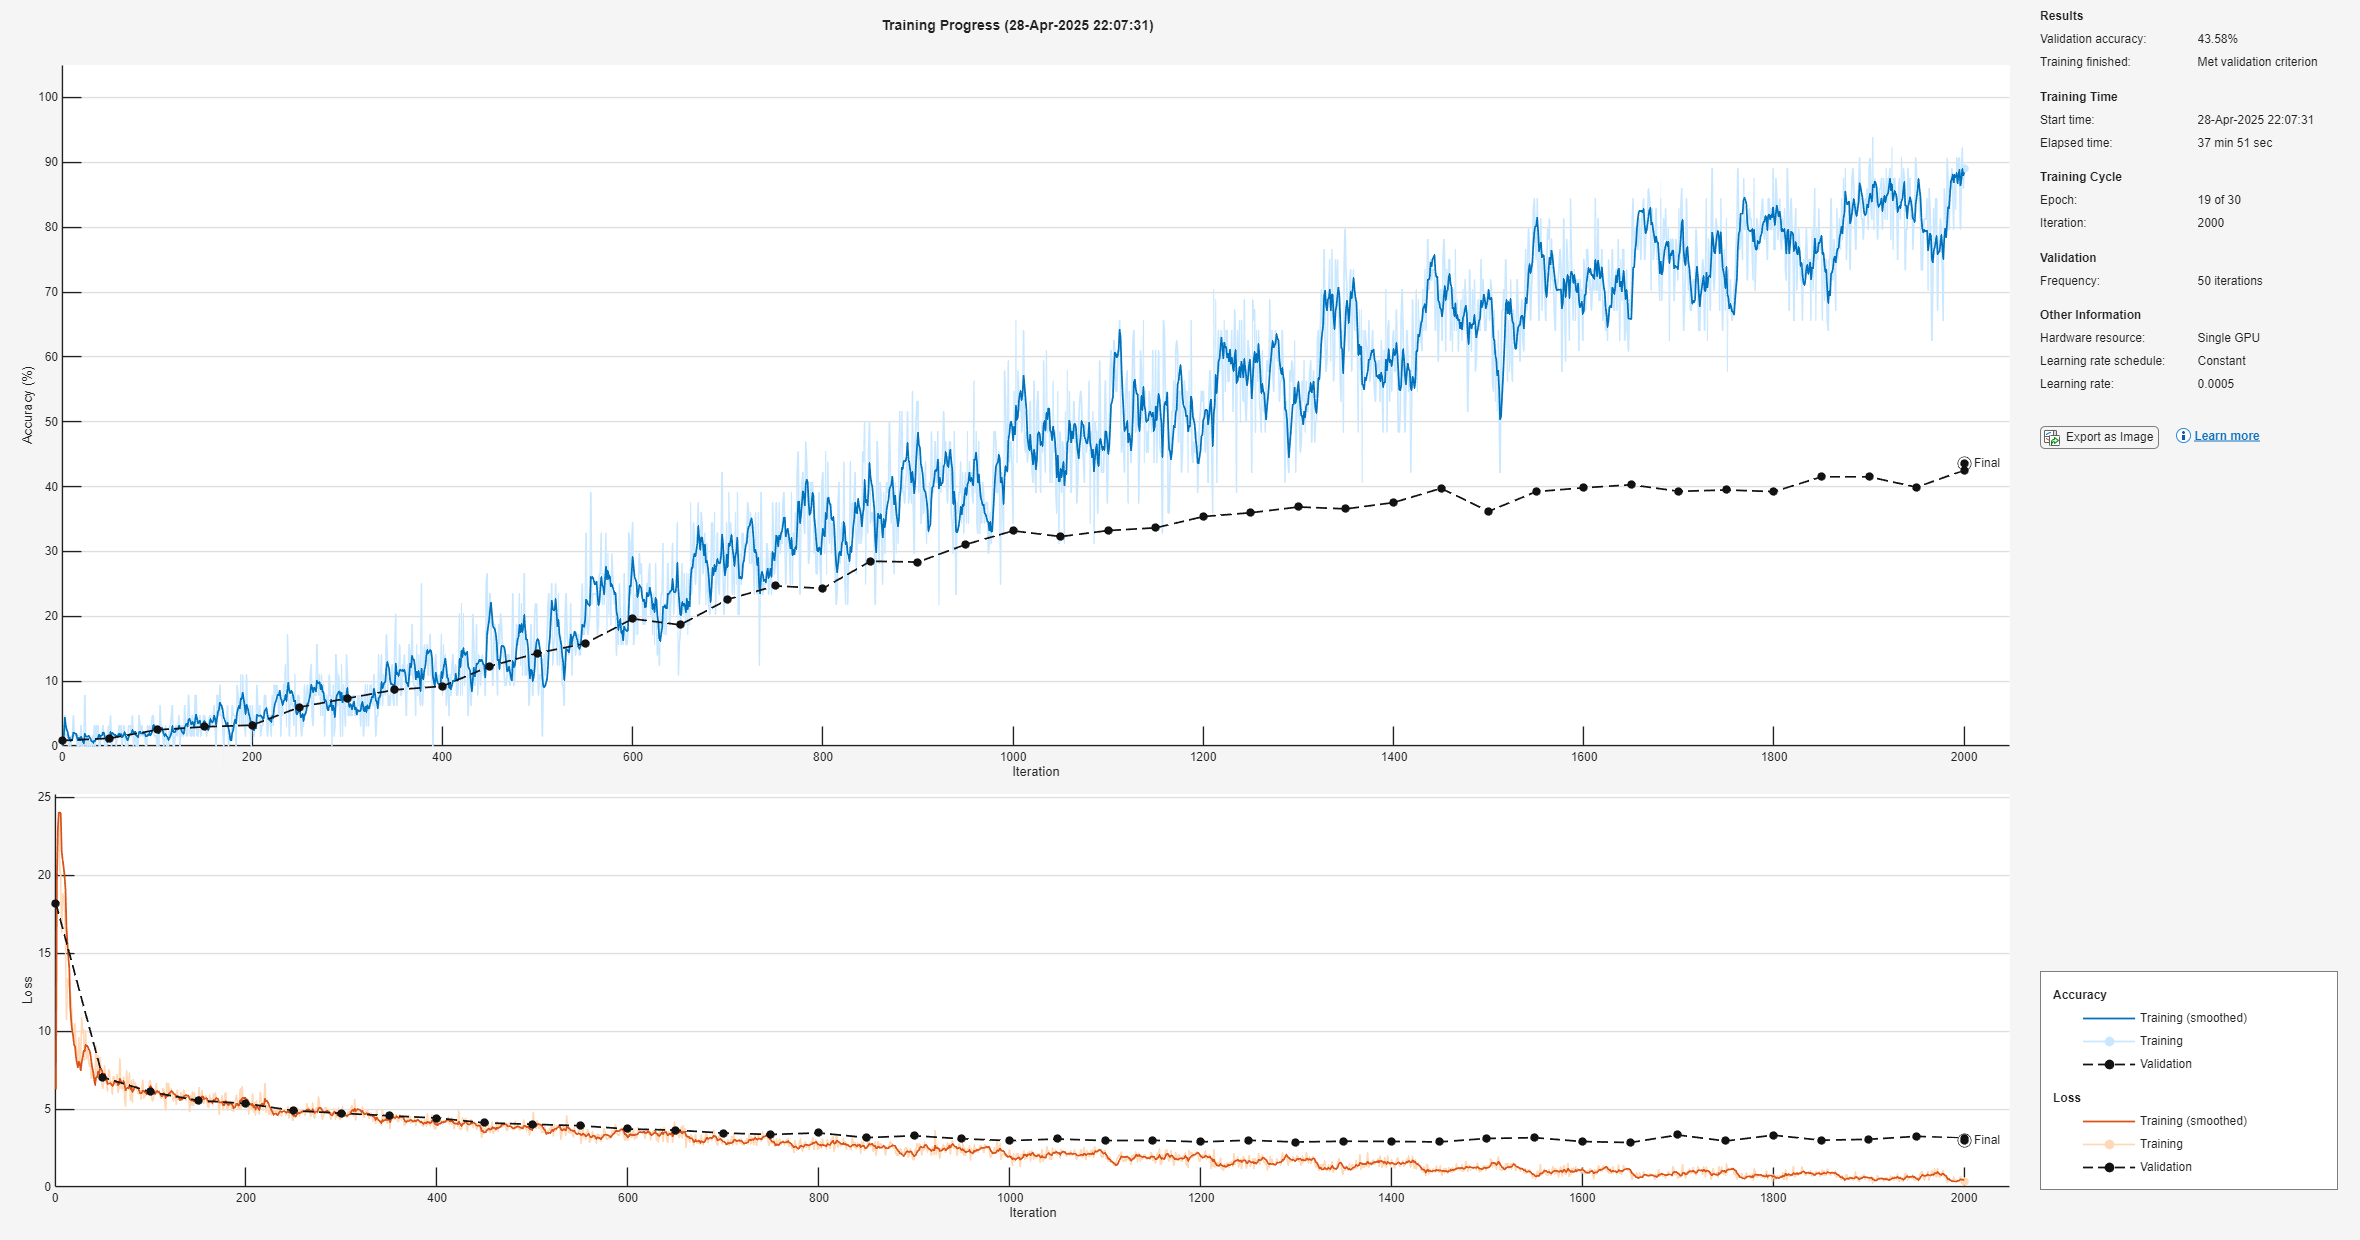

Accuracy for Fold 3: 43.37%


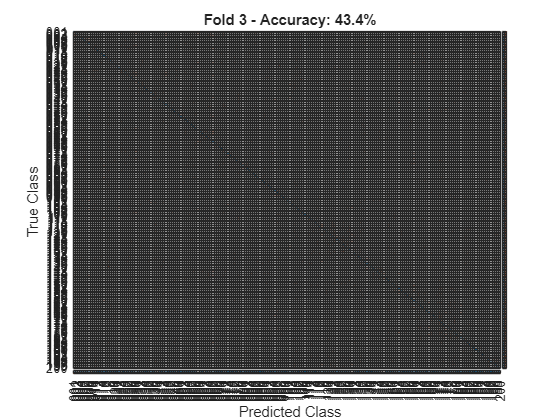

Running Fold 4


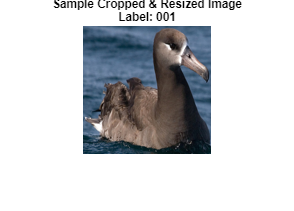

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |        0.00% |        0.97% |       6.6230 |      18.0728 |          0.0005 |
|       1 |           2 |       00:00:21 |        0.00% |              |      18.3809 |              |          0.0005 |
|       1 |           3 |       00:00:22 |        1.56% |              |      24.8546 |              |          0.0005 |
|       1 |           4 |       00:00:22 |        1.56% |              |      22.2681 |              |          0.

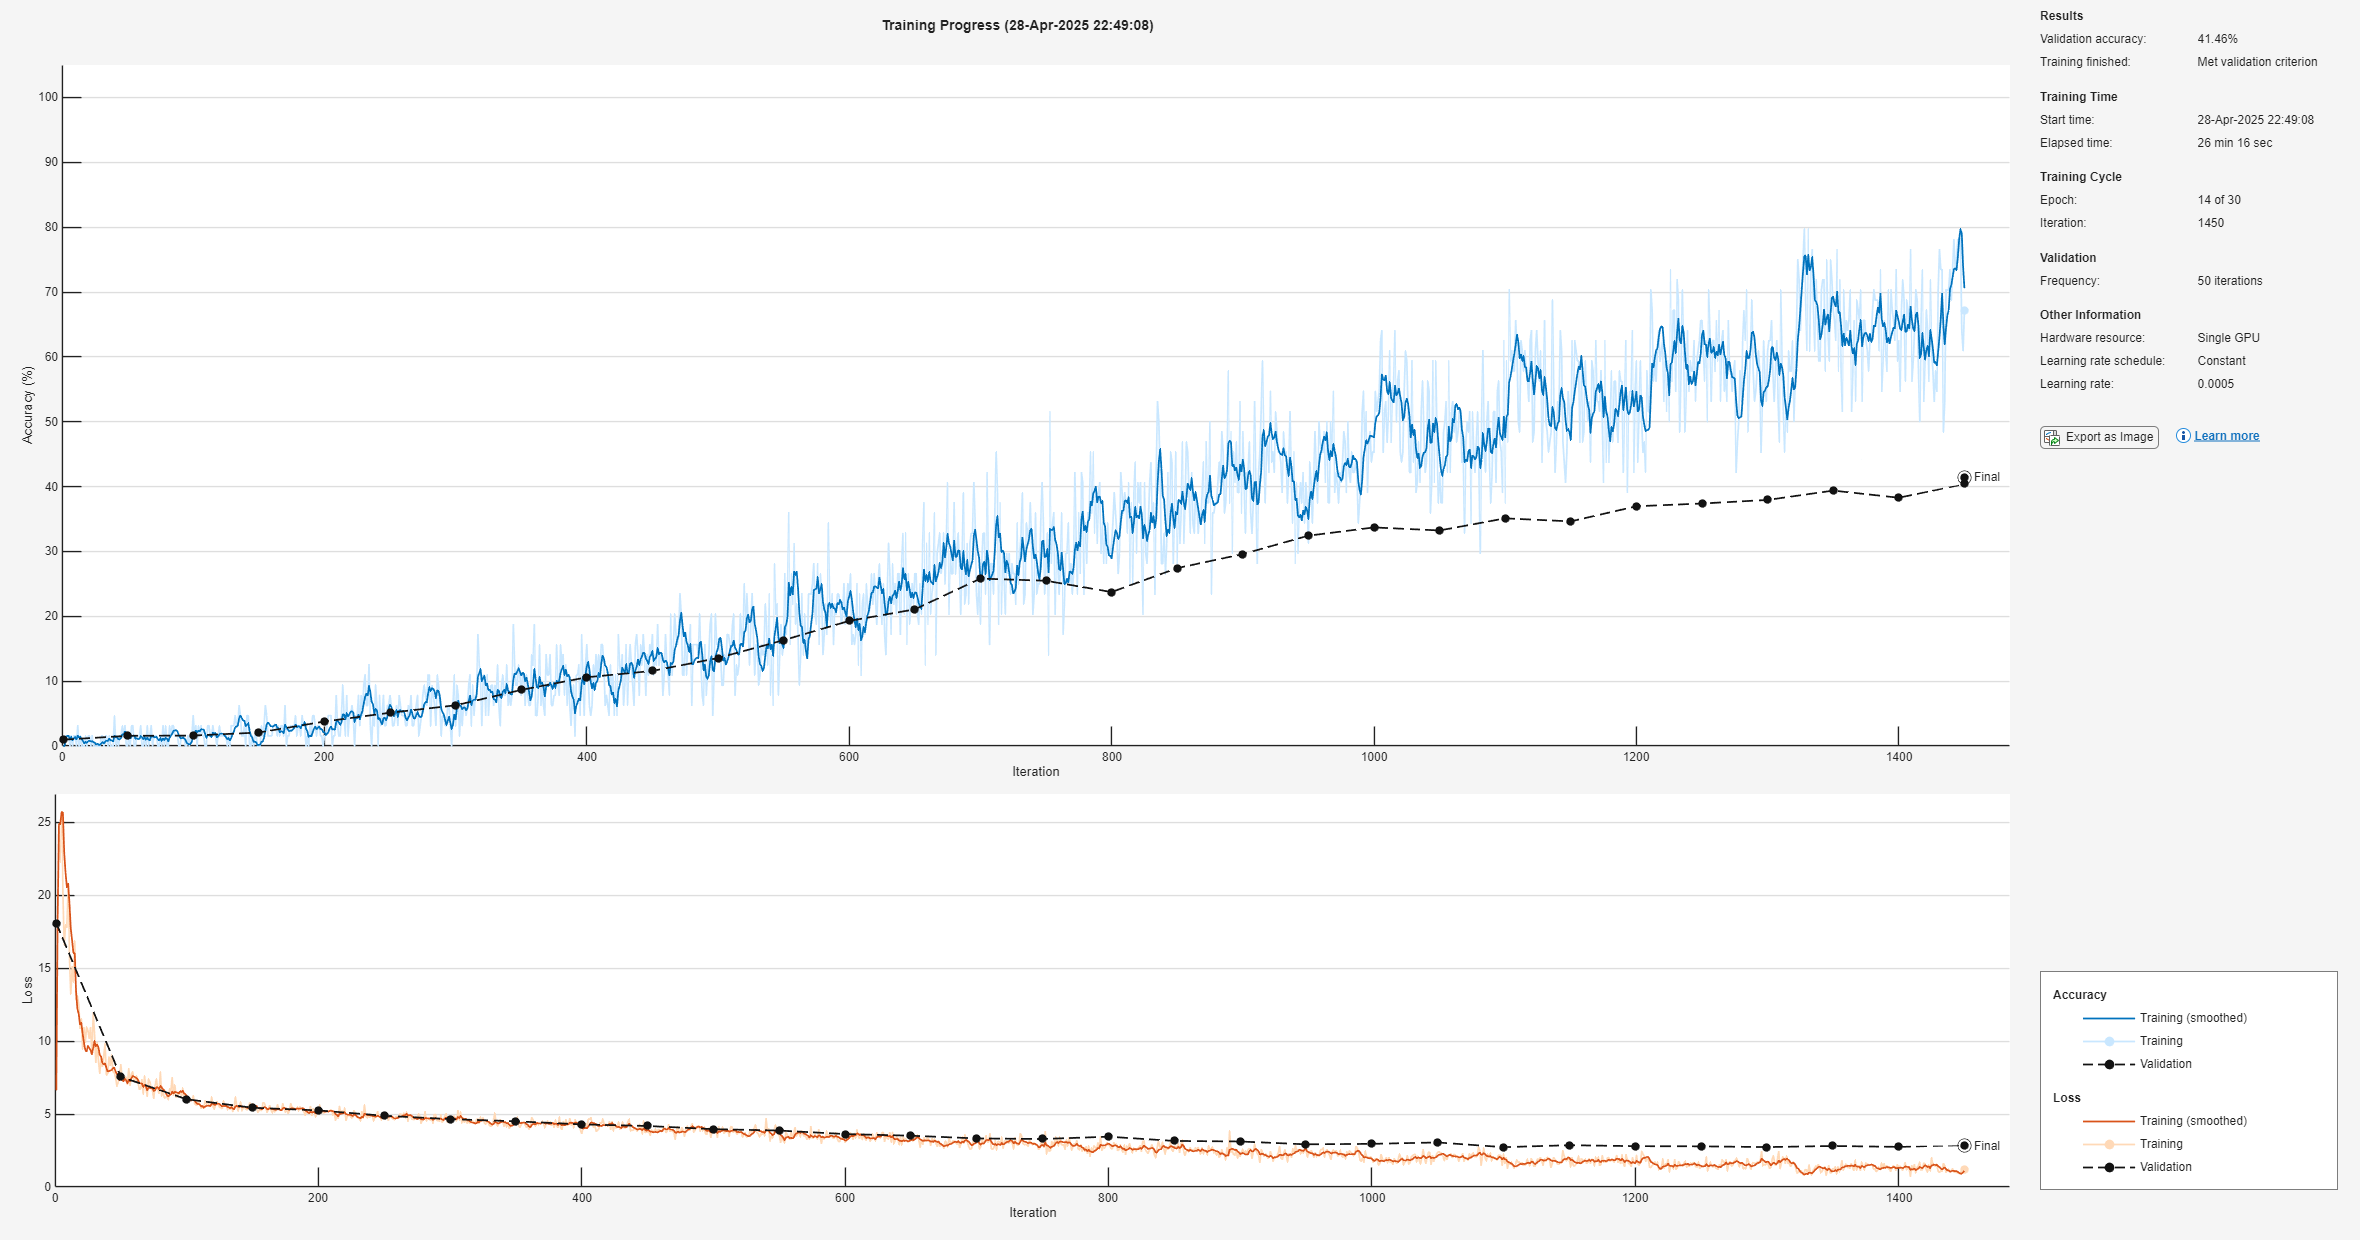

Accuracy for Fold 4: 41.40%


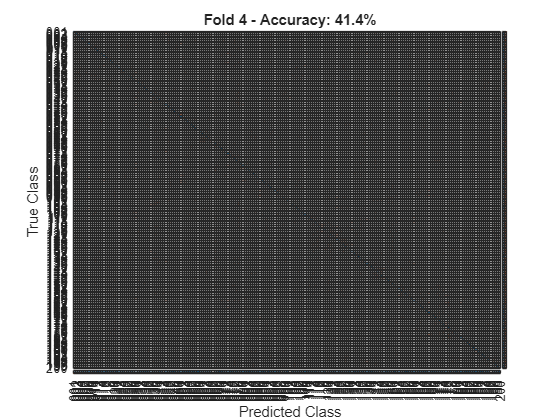

Running Fold 5


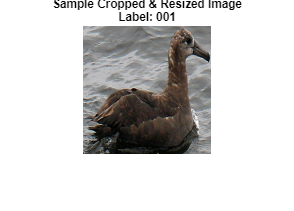

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:22 |        0.00% |        0.81% |       6.5697 |      17.4925 |          0.0005 |
|       1 |           2 |       00:00:22 |        0.00% |              |      15.5312 |              |          0.0005 |
|       1 |           3 |       00:00:23 |        1.56% |              |      27.6349 |              |          0.0005 |
|       1 |           4 |       00:00:23 |        0.00% |              |      24.3659 |              |          0.

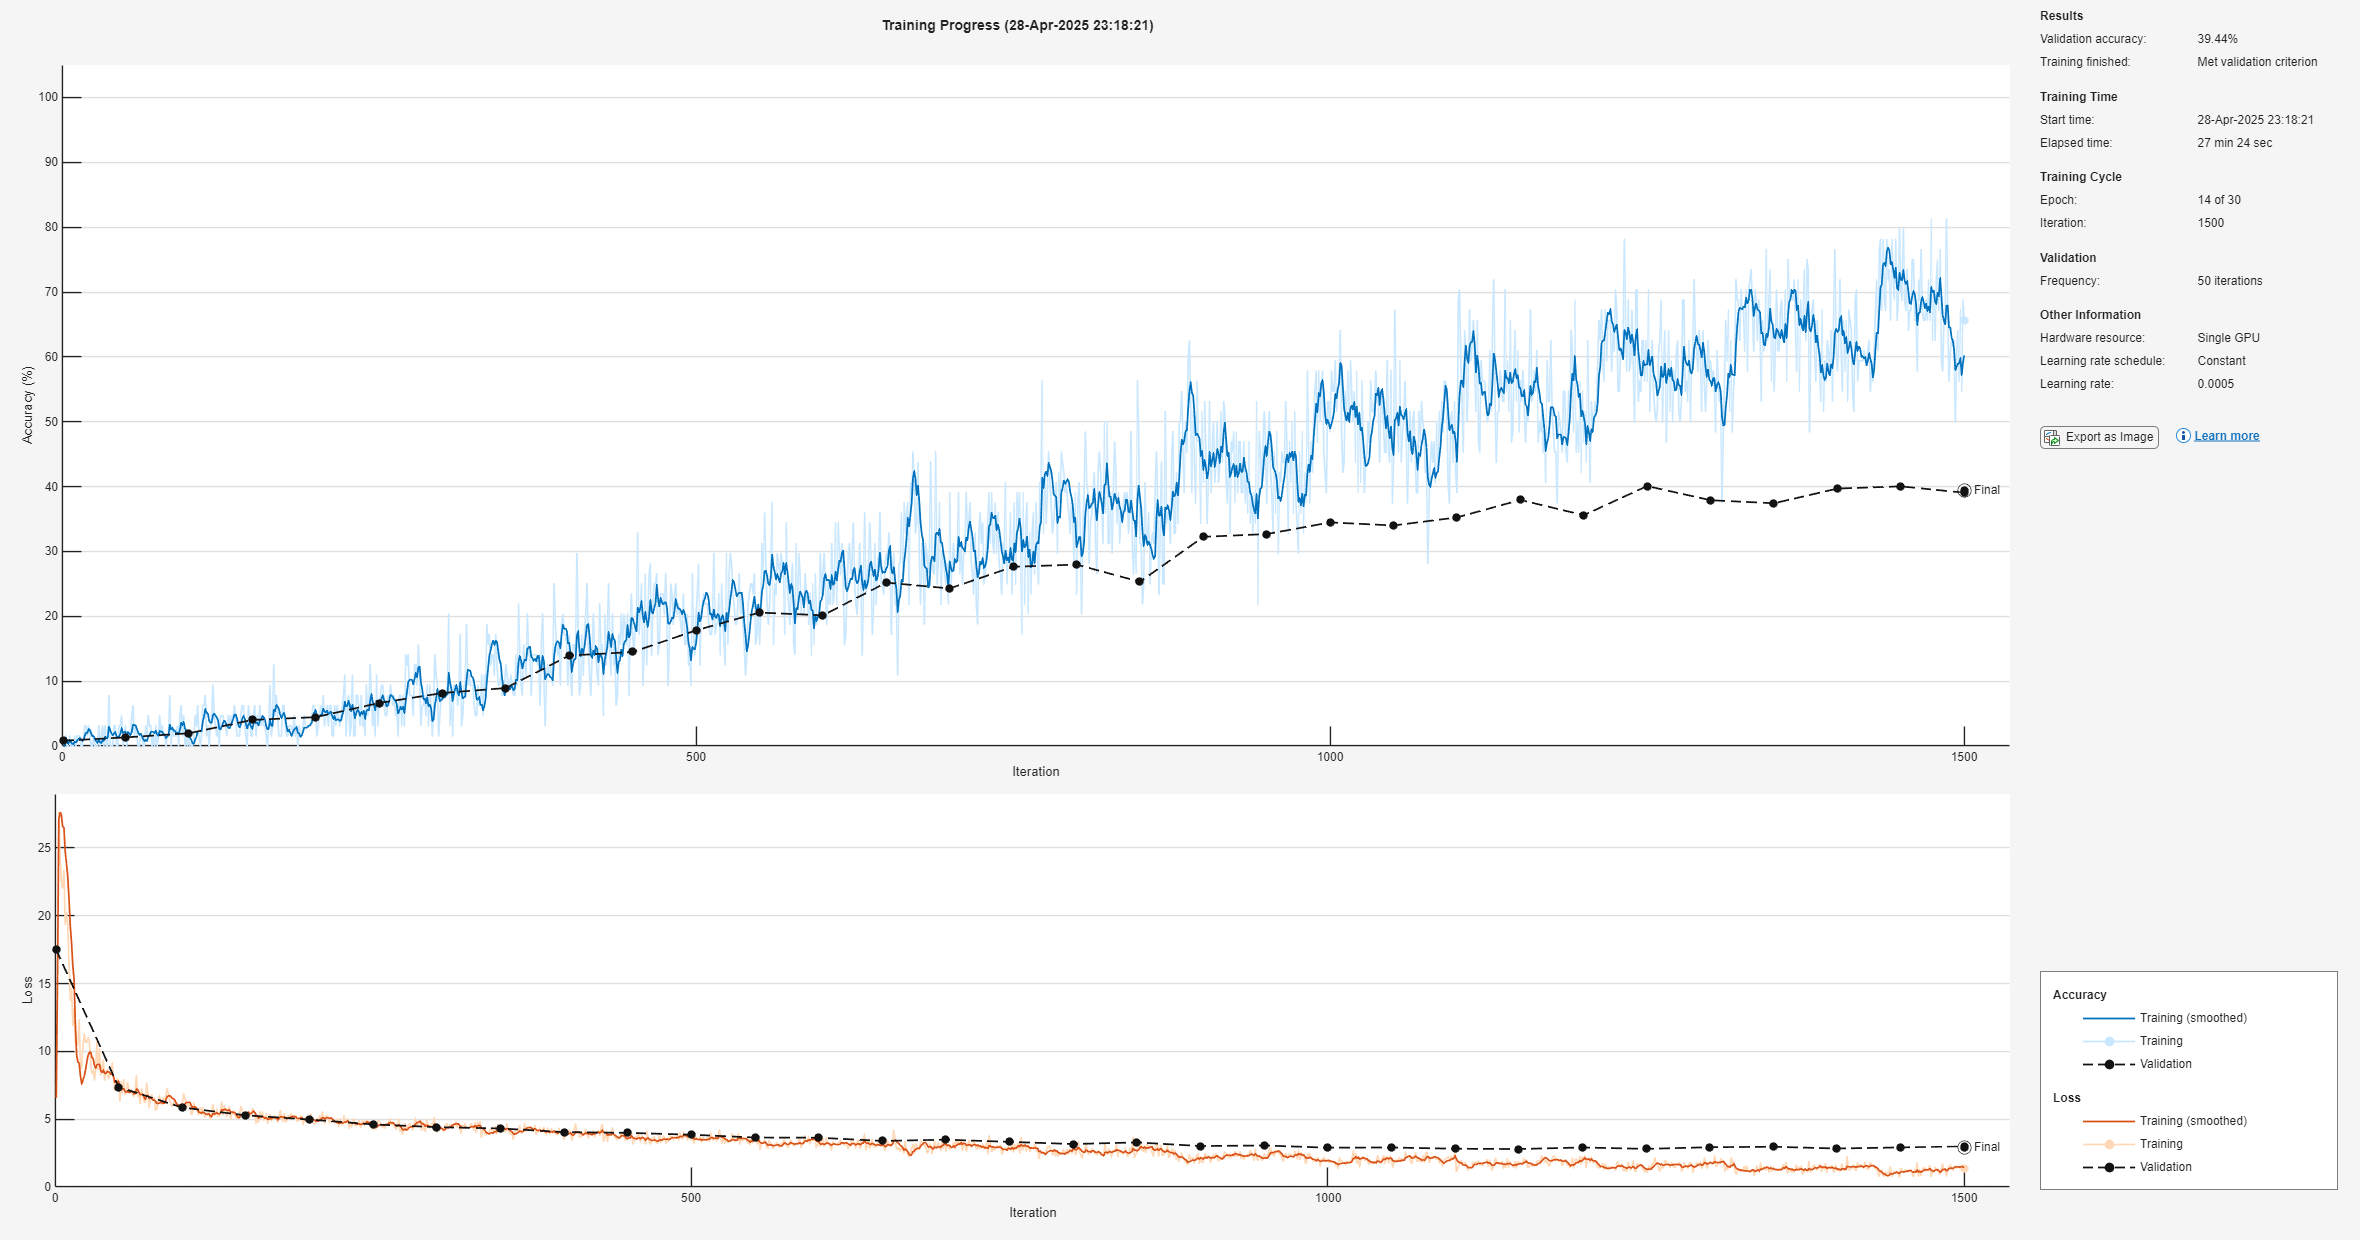

Accuracy for Fold 5: 37.86%


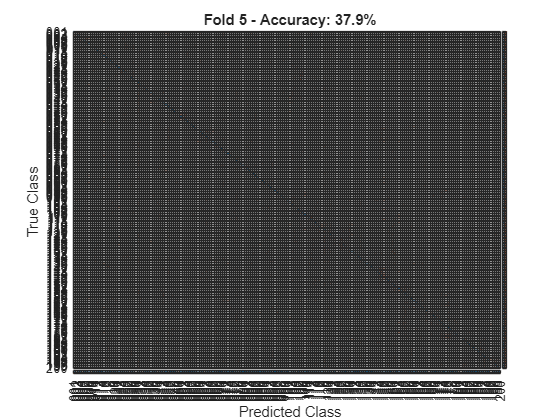

numFolds = 5;
accuracy_overall = 0;

for iRun = 1:numFolds
    disp("Running Fold " + iRun);

    % Get training/validation/test sets for this fold
    [cdsTraining, cdsValidation, cdsTest, trainingImageDS, validationImageDS, testImageDS] = ...
        getFoldsFor5FoldCrossVal(iRun, fold1DS, fold2DS, fold3DS, fold4DS, fold5DS, folder, imgTxtFolder, targetSize);

    % Display a Cropped and Resized Sample Image from Training Set
    sampleData = read(cdsTraining);
    sampleImage = sampleData{1}; % Get the image part
    sampleLabel = sampleData{2}; % Get the label part

    figure;
    imshow(sampleImage);
    title(["Sample Cropped & Resized Image", "Label: " + string(sampleLabel)]);
    reset(cdsTraining); % Reset after reading sample
    
    %% STEP 7: Set Training Options
    options = trainingOptions('adam', ...
        'InitialLearnRate', 0.0005, ...
        'MiniBatchSize', 64, ...
        'MaxEpochs', 30, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', cdsValidation, ...
        'ValidationFrequency', 50, ...
        'ValidationPatience', 7, ...
        'ExecutionEnvironment', 'gpu', ...
        'Verbose', true, ...
        'VerboseFrequency', 1, ...
        'Plots', 'training-progress');

    % Train the model
    simpleCNN = trainNetwork(cdsTraining, layers, options);

    % Test prediction
    YPred = classify(simpleCNN, cdsTest, 'ExecutionEnvironment', 'gpu');
    YTest = testImageDS.Labels;

    % Fold accuracy
    accuracy = sum(YPred == YTest) / numel(YTest);
    disp("Accuracy for Fold " + string(iRun) + ": " + num2str(accuracy*100, '%.2f') + "%");

    % Plot confusion matrix
    [m, order] = confusionmat(YTest, YPred);
    figure;
    cm = confusionchart(m, order, 'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized');
    title("Fold " + string(iRun) + " - Accuracy: " + string(round(accuracy*100, 1)) + "%");

    % Update overall accuracy
    accuracy_overall = accuracy_overall + accuracy;
end

## Average Accuracy

disp("Average Accuracy across 5 folds: " + num2str((accuracy_overall/numFolds)*100, '%.2f') + "%");

Average Accuracy across 5 folds: 41.45%
